# Inverse Filtering Analysis

#### Load the images I1 and I2

load("img_restoration.mat");

#### Visualize Images

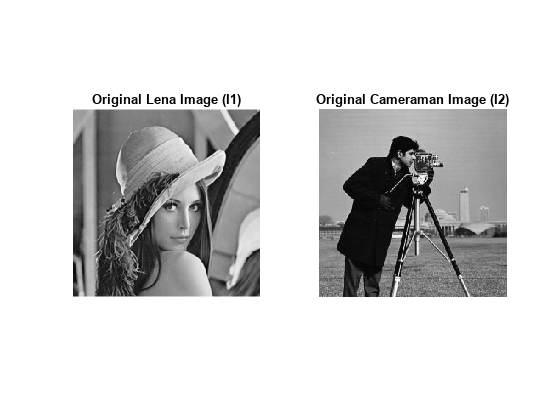

figure;
subplot(1, 2, 1); imshow(I1, []); title("Original Lena Image (I1)");
subplot(1, 2, 2); imshow(I2, []); title("Original Cameraman Image (I2)");

#### Choose one of the Images

original_image = I2; %choose between I1 and I2

#### Apply Linear Motion Deformation

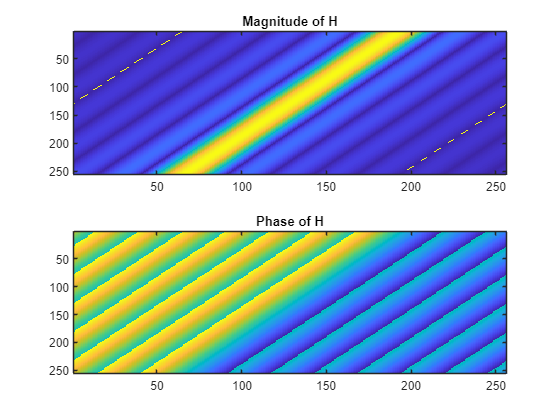

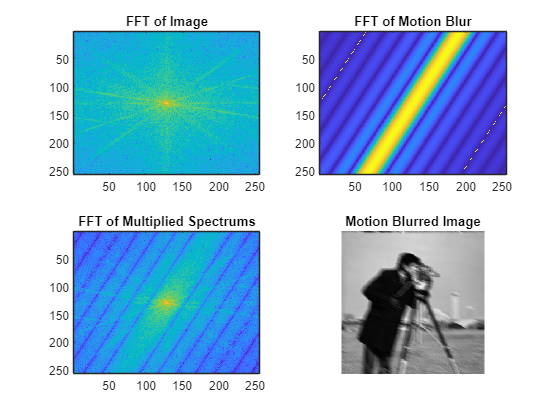

a = 10; % Horizontal motion coefficient
b = 5; % Vertical motion coefficient
T = 1; % Exposure time
[motion_blurred_image,  motion_blur_kernel_spectrum] = applyLinearMotionBlur(a, b, T, original_image, true);

#### Add Gaussian noise

mean = 0;
variance = 10;
noise = mean + sqrt(variance) * randn(size(motion_blurred_image));
noisy_motion_blurred_image = motion_blurred_image + noise;

#### Visualize Motion Blurred Noisy Image

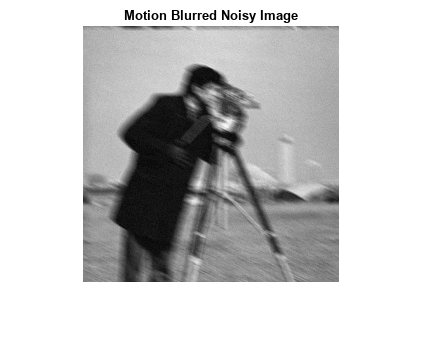

figure; imshow(noisy_motion_blurred_image, []); title("Motion Blurred Noisy Image");

#### Apply Inverse filtering to the image with different noise values

var_vec = 0:5:100;
snr_db_values = zeros(size(var_vec));
mse_values = zeros(size(var_vec));
restored_images = cell(size(var_vec));
max_snr = -inf;
min_mse = 0;
best_performed_var = 0;
for i = 1:length(var_vec)
    mean = 0;
    noise = mean + sqrt(var_vec(i)) * randn(size(motion_blurred_image));
    motion_blurred_noisy_image = motion_blurred_image + noise;

    restored_image = inverseFilter(motion_blurred_noisy_image, motion_blur_kernel_spectrum, false);
    snr_db_values(i) = computeSNR_db(original_image, restored_image);
    mse_values(i) = computeMSE(original_image, restored_image);
    restored_images{i} = restored_image;
    if (snr_db_values(i) > max_snr)
        best_restored_image = restored_image;
        min_mse = mse_values(i);
        max_snr = snr_db_values(i);
        best_performed_var = var_vec(i);
    end
end

#### Save restored images (Optional)

folder_name = "Restored_images_inverse_a" + a + "_b" + b + "_T" + T + "/" ;
if ~exist(folder_name), mkdir(folder_name), end

for i = 1:length(restored_images)
    file_name = "SNR_" + snr_db_values(i) + "_MSE_" + mse_values(i) + "_var_" + varience_vec(i) + ".png";
    imwrite(uint8(restored_images{i}), folder_name + file_name);
end

#### Plot the SNR (dB) values and MSE values corresponding to different variance values

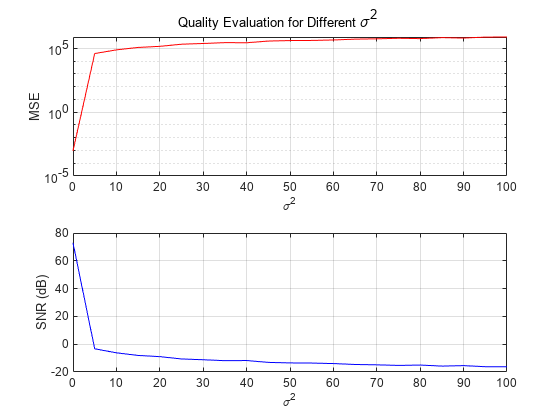

figure;
subplot(2, 1, 1); semilogy(var_vec, mse_values, "Color", "red"); xlabel("\sigma^2"); ylabel("MSE"); grid on;
subplot(2, 1, 2); plot(var_vec, snr_db_values, "Color", "blue"); xlabel("\sigma^2"); ylabel("SNR (dB)"); grid on;
sgtitle("Quality Evaluation for Different \sigma^2 ");

#### Visualize the results of best choice of variance 

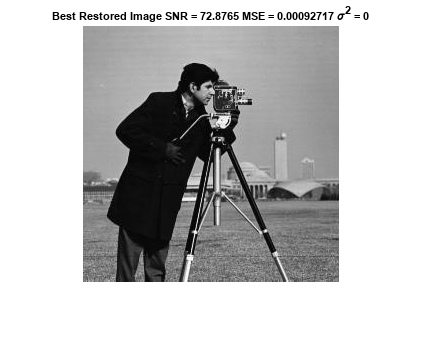

figure;
title_text = "Best Restored Image SNR = " + max_snr ...
    + " MSE = " + min_mse + " \sigma^2 = " + best_performed_var;
imshow(best_restored_image, []); title(title_text);

#### Now compute the inverse filtered image for only a motion blurred image

restored_image = inverseFilter(motion_blurred_image, motion_blur_kernel_spectrum, 0, true);
snr_db_values_motion = computeSNR_db(original_image, restored_image);
mse_values_motion = computeMSE(original_image, restored_image);

# Geometric Mean Filtering Analysis

### Applying the geometric mean filter with only motion blur

alpha = 0.5;
beta = 1;
restored_image_gm = GeometricMeanFilter(motion_blurred_image, motion_blur_kernel_spectrum, alpha,beta,0, true);
snr_db_values_motion_gm = computeSNR_db(original_image, restored_image);
mse_values_motion_gm = computeMSE(original_image, restored_image);

#### Using Different K values Apply Geometric Mean Filter to the Noisy Image

mean = 0;
variance = 10;
noise = mean + sqrt(variance) * randn(size(motion_blurred_image));
noisy_motion_blurred_image = motion_blurred_image + noise;
k = -10:0.01:10;
k = exp(k);
snr_db_values = zeros(size(k));
mse_values = zeros(size(k));
max_snr = 0;
min_mse = 0;
best_k = 0;
alpha = 0.5;
beta = 1;
for i = 1:length(k)
    restored_image = GeometricMeanFilter(noisy_motion_blurred_image, motion_blur_kernel_spectrum,alpha,beta, k(i), false);
    snr_db_values(i) = computeSNR_db(original_image, restored_image);
    mse_values(i) = computeMSE(original_image, restored_image);
    if (snr_db_values(i) > max_snr)
        best_restored_image = restored_image;
        min_mse = mse_values(i);
        max_snr = snr_db_values(i);
        best_k = k(i);
    end
end

#### Plot the SNR (dB) values and MSE values corresponding to different K values

figure;
subplot(2, 1, 1); loglog(k, mse_values, "Color", "red"); xlabel("k"); ylabel("MSE"); grid on;
subplot(2, 1, 2); semilogx(k, snr_db_values, "Color", "blue"); xlabel("k"); ylabel("SNR (dB)"); grid on;
sgtitle("Quality Evaluation for \sigma^2 = " + variance);

#### Visualize the results of best K for a certain noise power

figure;
title_text = "Best Restored Image SNR = " + max_snr ...
    + " MSE = " + min_mse + " K = " + best_k;
imshow(best_restored_image, []); title(title_text);

#### Loop through various noise powers and find best K for each where alpha is constant

varience_vec = 0:5:100;
best_k_vec = zeros(size(varience_vec));
max_snr_vec = zeros(size(varience_vec));
min_mse_vec = zeros(size(varience_vec));
alpha = 0.3;
beta =1;
k = -10:0.1:10;
k = exp(k);
snr_db_values = zeros(size(k));
mse_values = zeros(size(k));

for j = 1:length(varience_vec)
    varience = varience_vec(j);
    mean = 0;
    noise = mean + sqrt(varience) * randn(size(motion_blurred_image));
    noisy_motion_blurred_image = motion_blurred_image + noise;
    max_snr = 0;
    min_mse = 0;
    best_k = 0;
    for i = 1:length(k)
        restored_image = GeometricMeanFilter(noisy_motion_blurred_image, motion_blur_kernel_spectrum,alpha,beta, k(i), false);
        snr_db_values(i) = computeSNR_db(original_image, restored_image);
        mse_values(i) = computeMSE(original_image, restored_image);
        if (snr_db_values(i) > max_snr)
            best_restored_image = restored_image;
            min_mse = mse_values(i);
            max_snr = snr_db_values(i);
            best_k = k(i);
        end
    end
    min_mse_vec(j) = min_mse;
    max_snr_vec(j) = max_snr;
    best_k_vec(j) = best_k;
    %disp(j)
end

#### Plot the metrics

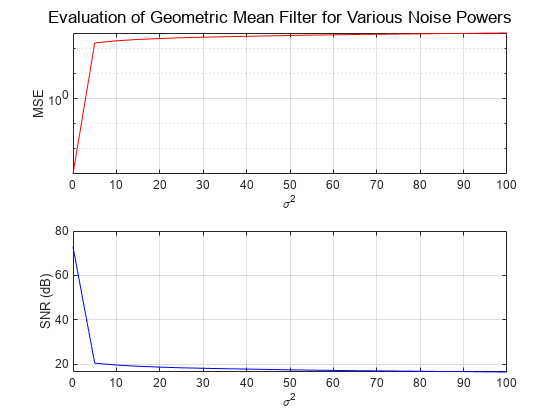

figure;
subplot(2, 1, 1); semilogy(varience_vec, min_mse_vec, "Color", "red"); xlabel("\sigma^2"); ylabel("MSE"); grid on;
subplot(2, 1, 2); plot(varience_vec, max_snr_vec, "Color", "blue"); xlabel("\sigma^2"); ylabel("SNR (dB)"); grid on;
sgtitle("Evaluation of Geometric Mean Filter for Various Noise Powers");

## Loop through various alpha values K to find best combination in terms of SNR

varience_vec = 0:5:100;
alphas = 0:0.05:1;
beta =1;
k = -10:0.1:10;
k = [0 exp(k)];

max_snr_vec = zeros(size(varience_vec));
min_mse_vec = zeros(size(varience_vec));
best_k_vec = zeros(size(varience_vec));
best_alpha_vec = zeros(size(varience_vec));
best_restored_images = cell(size(varience_vec));
for l = 1:length(varience_vec)
    varience = varience_vec(l);
    mean = 0;
    noise = mean + sqrt(varience) * randn(size(motion_blurred_image));
    noisy_motion_blurred_image = motion_blurred_image + noise;

    max_snr = -inf;
    min_mse = 0;
    best_k = 0;
    best_alpha = -1;
    for j = 1:length(alphas)
        alpha = alphas(j);

        for i = 1:length(k)
            restored_image = GeometricMeanFilter(noisy_motion_blurred_image, motion_blur_kernel_spectrum,alpha, beta, k(i), false);
            snr_db_value = computeSNR_db(original_image, restored_image);
            mse_value = computeMSE(original_image, restored_image);
            if (snr_db_value > max_snr)
                best_restored_image = restored_image;
                min_mse = mse_value;
                max_snr = snr_db_value;
                best_k = k(i);
                best_alpha = alpha;
            end
        end
    end
    best_restored_images{l} = best_restored_image;
    max_snr_vec(l) = max_snr;
    min_mse_vec(l) = min_mse;
    best_k_vec(l) = best_k;
    best_alpha_vec(l) = best_alpha;

    disp(['Completed Variance iteration: ', num2str(l)]);
end

Completed Variance iteration: 1
Completed Variance iteration: 2
Completed Variance iteration: 3


## Save restored images

folder_name = "Restored_images_geometric_a" + a + "_b" + b + "_T" + T + "/" ;
if ~exist(folder_name), mkdir(folder_name), end

for i = 1:length(best_restored_images)
    file_name = "SNR_" + max_snr_vec(i) + "_MSE_" + min_mse_vec(i) + "_var_" + varience_vec(i)+ "_alpha_" + best_alpha_vec(i) + "_k_" + best_k_vec(i) + ".png";
    imwrite(uint8(best_restored_images{i}), folder_name + file_name);
end